# Ejemplo Práctico: Tienda de Neumaticos

Nos encargan que debemos ordenar por su codigo la siguiente informacion de una tienda de neumaticos

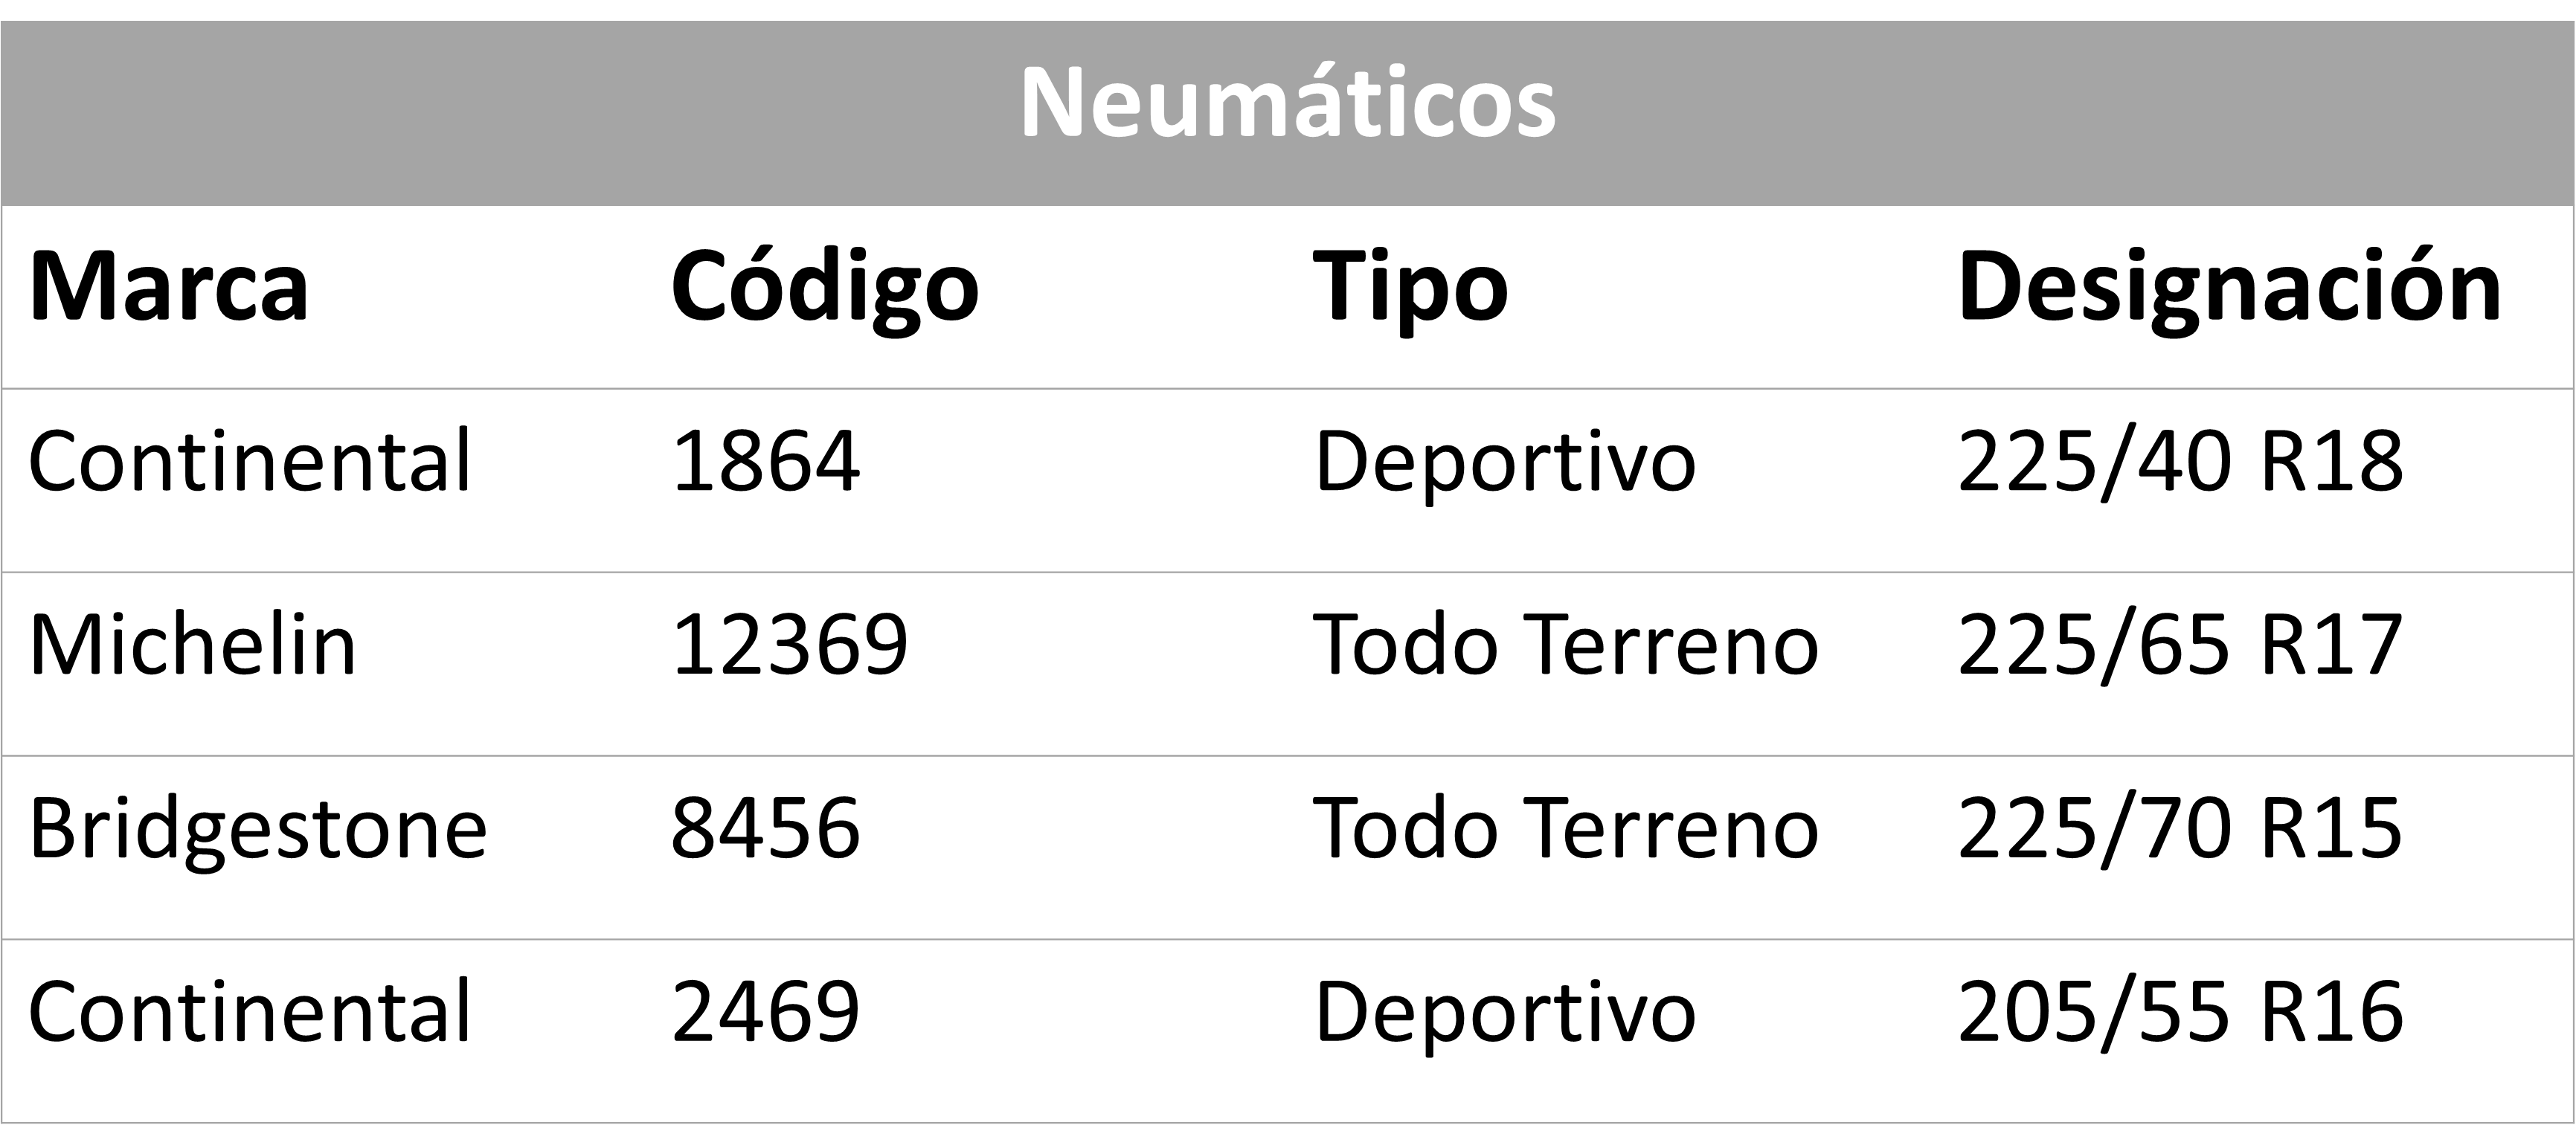

## Creacion del vector de estructuras

neumaticos(1) = struct('marca','Continental','codigo',1864,'tipo','Deportivo','designacion','225/40 R18');
neumaticos(2) = struct('marca','Michelin','codigo',12369,'tipo','Todo Terreno','designacion','225/65 R17');
neumaticos(3) = struct('marca','Bridgestone','codigo',8456,'tipo','Todo Terreno','designacion','225/70 R15');
neumaticos(4) = struct('marca','Continental','codigo',2469,'tipo','Deportivo','designacion','205/55 R16');
neumaticos

neumaticos = 1×4 struct array with fields:
    marca
    codigo
    tipo
    designacion


## Funcion de ordenamiento

Llamar la funcion

neumaticosOrdenados = ordenarNeumaticos(neumaticos,'codigo')

neumaticosOrdenados = 1×4 struct array with fields:
    marca
    codigo
    tipo
    designacion


Crear la funcion

function vecOrdenado = ordenarNeumaticos(neumaticos, nombreCampo)
%Comprobar si el nombre del campo de verdad pertenece a la estructura
if isfield(neumaticos,nombreCampo)
    %Aplicar el algoritmo de ordenamiento
    for i = 1:length(neumaticos)-1
        idxMenor = i;
        for j = i+1:length(neumaticos)
            if neumaticos(j).(nombreCampo) < neumaticos(idxMenor).(nombreCampo)
                idxMenor = j;
            end
        end
        %Intercambiar la posicion de los elementos
        temp = neumaticos(i);
        neumaticos(i) = neumaticos(idxMenor);
        neumaticos(idxMenor) = temp;
    end
    vecOrdenado = neumaticos;
else
    vecOrdenado = [];
end
end